Section 2

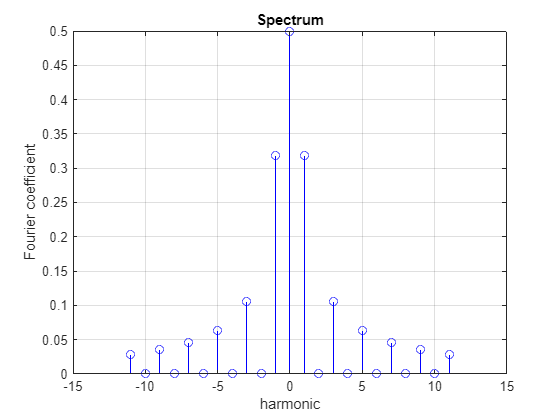

init();
M = 11; % number of harmonics
T = 1e-3; % waveform period
[m,cm] = create_cm_series(M,T); % create Fourier coefficients
t = 0:2e-3/1000:2e-3; % 1001 points from 0 to 2 ms
[y] = cm2yt(t,T,m,cm,M);
make_stem(m,cm,'Spectrum','harmonic','Fourier coefficient');

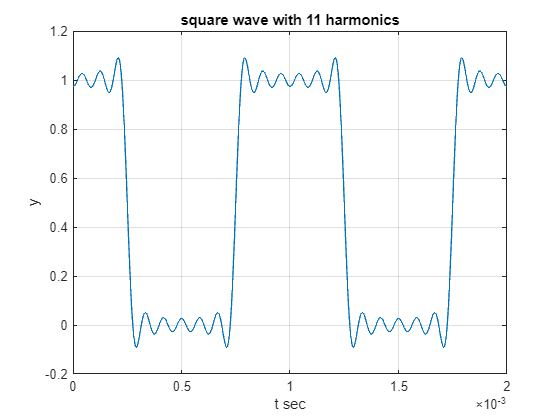

make_plot(t,y,'square wave with 11 harmonics','t sec','y');

Section 3

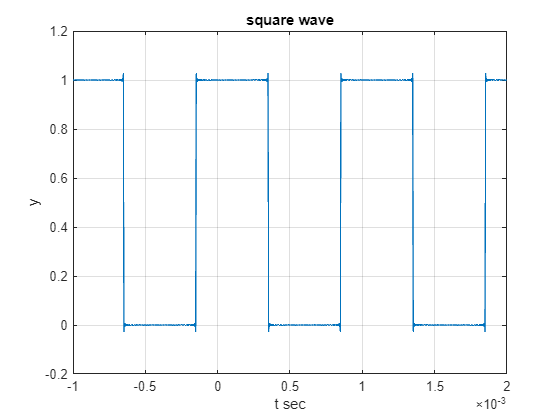

function [m,cm] = create_cm_series2(M,T)
 m = -M:M;
 A = 1;
 wo = 2 * pi / T;
 tp = 0.1e-3; % delay
 cm = (sin(m*pi/2)./(m*pi)).*(exp(-1j*m*wo*tp));
 cm(m == 0) = 0.5;
 % zero_ind = find(m==0);
 % cm(zero_ind) = 0; % set DC value, avoid infinite cm @ m = 0;
end
M = 800; % number of harmonics
T = 1e-3; % waveform period
[m,cm] = create_cm_series2(M,T); % create Fourier coefficients
t = -1e-3:2e-3/1000:2e-3; 
[y] = cm2yt(t,T,m,cm,M);
make_plot(t,y,'square wave','t sec','y');